# Laborator 6

## Probleme

## P1

x = [300 304 305 307 310];
y = [2.4771 2.4829 2.4843 2.4871 2.4914];
t = 306;
v = Lagrange(x,y,t);
fprintf("My Lagrange log10: %f",v);

My Lagrange log10: 2.485698

fprintf("MATLAB log10: %f",log10(t));

MATLAB log10: 2.485721

## P2

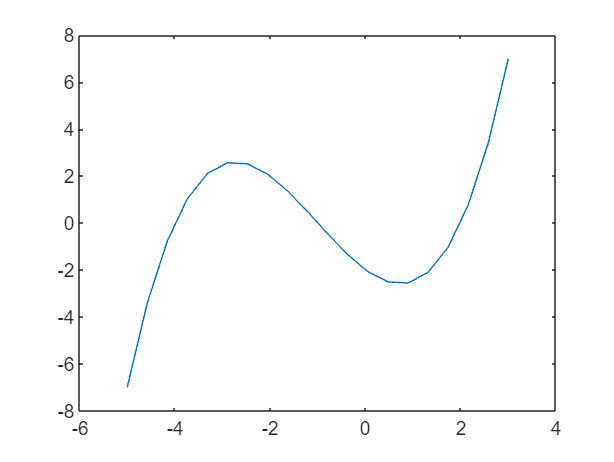

clear all
syms x;
f(x) = (x^3 + 3*x^2 - 6*x - 8) / 4;
x = linspace(-5,3,20); 
plot(x,f(x));

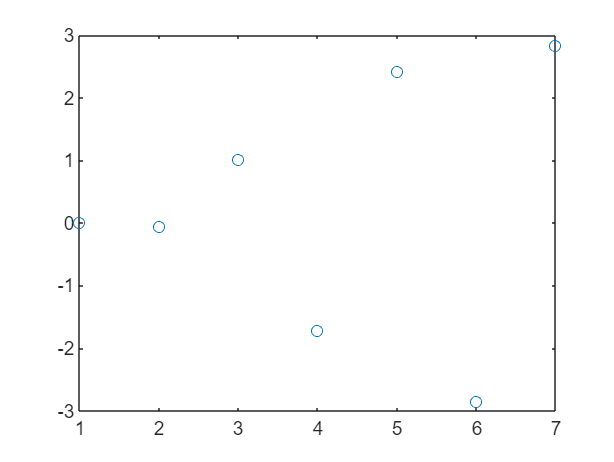


grades = [1 5 8 9 10 11 12];
xi = 1.567;
pols = Lagrange_polynomials_for_given_grade(x,xi,grades);
plot(pols,'o')

## P3

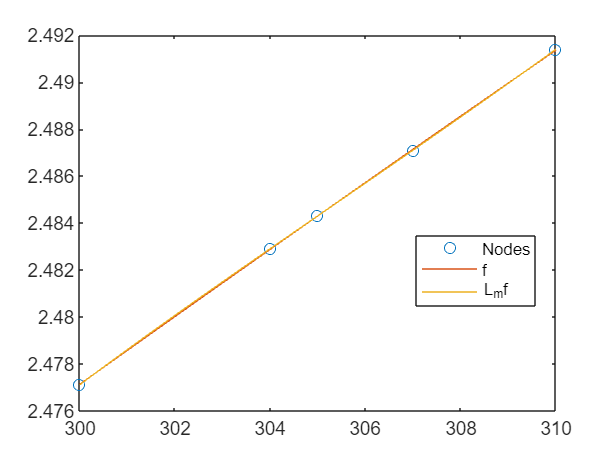

x = [300 304 305 307 310];
y = [2.4771 2.4829 2.4843 2.4871 2.4914];
t= linspace(300,310);
vl=Lagrange(x,y,t);
plot(x,y,'o',t,log10(t),t,vl)
legend('Nodes','f','L_mf','Location', 'best')

## P4

x = [300 304 305 307 310];
y = [2.4771 2.4829 2.4843 2.4871 2.4914];
t = 306;
v = baryLagrange(x,y,t);
fprintf("My BaryLagrange log10: %f",v);

My BaryLagrange log10: 2.485698

fprintf("MATLAB log10: %f",log10(t));

MATLAB log10: 2.485721

## Probleme practice

## P1

x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
t = 1975;
v = baryLagrange(x, y, t);
fprintf("1975 population : %f",v);

1975 population : 214.364389


x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];
t = 2018;
v = baryLagrange(x, y, t);
fprintf("My 2018 USA population (all info): %f",v);

My 2018 USA population (all info): -664.306813



x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];

x = x(8:size(x,2));
y = y(8:size(y,2));
t = 2018;
v = baryLagrange(x, y, t);
fprintf("My 2018 USA population : %f",v);

My 2018 USA population : 304.708787

fprintf("Actual 2018 USA population: %f",326.69);

Actual 2018 USA population: 326.690000


fprintf("My 2018 USA population (last 5) : %f",v);

My 2018 USA population (last 5) : 304.708787



x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];

x = x(9:size(x,2));
y = y(9:size(y,2));
t = 2018;
v = baryLagrange(x, y, t);
fprintf("My 2018 USA population (last 4): %f",v);

My 2018 USA population (last 4): 318.697408



x = [1900 1910 1920 1930 1940 1950 1960 1970 1980 1990 2000 2010];
y = [75.995 91.972 105.711 123.203 131.669 150.697 179.323 203.212 226.505 249.633 281.422 308.786];

x = x(10:size(x,2));
y = y(10:size(y,2));
t = 2018;
v = baryLagrange(x, y, t);
fprintf("My 2018 USA population (last 3): %f",v);

My 2018 USA population (last 3): 327.491200

## P2

clear  all
syms x;
f(x) = exp(x^2 - 1);
vals = [1 1.1 1.2 1.3 1.4];
y = eval(f(vals));
t = 1.25;
v = Lagrange(vals,y,t);
fprintf("My Lagrange value : %f",v);

My Lagrange value : 1.754957

fprintf("Actual function evaluation: %f",eval(f(t)));

Actual function evaluation: 1.755055

$$E_n(x) = \frac{f^{(n+1)}(\xi(x))}{(n+1)!} \times (x-x_0)(x-x_1)\cdots(x-x_n)$$  ==>> ERROR BOUND FORMULA

warning off
interval = [1 1.4];
f1 = @(x)exp(x^2 - 1)

f1 = function_handle with value:
    @(x)exp(x^2-1)


%f1_diff_6 = diff(f1,x,6)
f1_diff_6 = @(x)120*exp(x^2 - 1) + 720*exp(x^2 - 1) + 480*exp(x^2 - 1) + 64*exp(x^2 - 1);
max_diff_6 = calculateMaximumForInterval(f1_diff_6,interval);
vals = [1 1.1 1.2 1.3 1.4];

f2 = @(x)(x-1)*(x-1.1)*(x-1.2)*(x-1.3)*(x-1.4);
max2 = calculateMaximumForInterval(f2,interval);

E2 = max_diff_6/factorial(6)*max2;
fprintf("My calculated Error: %f",E2);

My calculated Error: 0.000180

fprintf("My Error Bound: %f",round(E2,4));

My Error Bound: 0.000200


actual_error = abs(eval(f(t)) - v);
fprintf("My Actual error : %f",actual_error);

My Actual error : 0.000097

## P3

syms z
x = [81 100 119 121 144 169 175];
y = [9 10 sqrt(119) 11 13 14 sqrt(175)];

% x = [25];
% y = [5];

t = 115;
f = sqrt(z);
z_funct = diff(f,z,9);

v = Lagrange(x,y,t);
fprintf("My Lagrange log10: %f",v);

My Lagrange log10: 10.746167

fprintf("MATLAB log10: %f",sqrt(t));

MATLAB log10: 10.723805


n = 1;
while true
    v = Lagrange(x,y,t);
    Rmf = f - v;
    try
        %eval(subs(T, val));
        aprox = vpa(abs(eval(subs(Rmf,t))));
        if  isnan(aprox) || aprox < power(10,-3)
            break
        end
    catch err
        warning(err.message)
        break
    end
    x(end+1) = x(end) + 1;
    y(end+1) = sqrt(x(end));

    x = [x(1)-1,x];
    y = [sqrt(x(1)),y];
    n = n+1;
end

fprintf("No iterations: %d",n);

No iterations: 2

fprintf("My Lagrange sqrt(115): %f",v);

My Lagrange sqrt(115): 10.723884

fprintf("MATLAB sqrt(115): %f",sqrt(t));

MATLAB sqrt(115): 10.723805

## P4

## Noduri echidistante

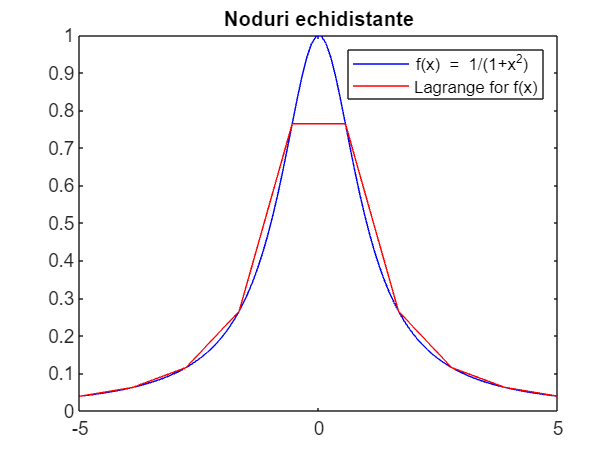


% ============ a) ===============
syms x
f(x) = 1/(1+x^2);
x = linspace(-5,5,100);
plot(x,f(x),'blue');
hold on
t = linspace(-5,5,10); 
y = f(x);
v = Lagrange(x,y,t);
plot(t,v,'red');
legend('f(x) = 1/(1+x^2)','Lagrange for f(x)')
title("Noduri echidistante")
hold off

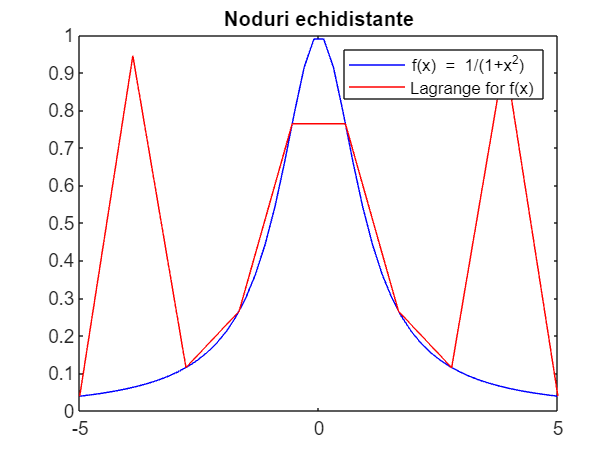


x = linspace(-5,5,50);
plot(x,f(x),'blue');
hold on
t = linspace(-5,5,10); 
y = f(x);
v = Lagrange(x,y,t);
plot(t,v,'red');
legend('f(x) = 1/(1+x^2)','Lagrange for f(x)')
title("Noduri echidistante")
hold off

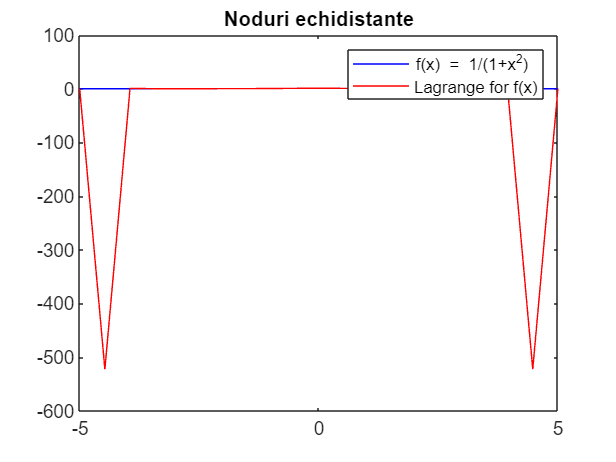



x = linspace(-5,5,50);
plot(x,f(x),'blue');
hold on
t = linspace(-5,5,20); 
y = f(x);
v = Lagrange(x,y,t);
plot(t,v,'red');
legend('f(x) = 1/(1+x^2)','Lagrange for f(x)')
title("Noduri echidistante")
hold off

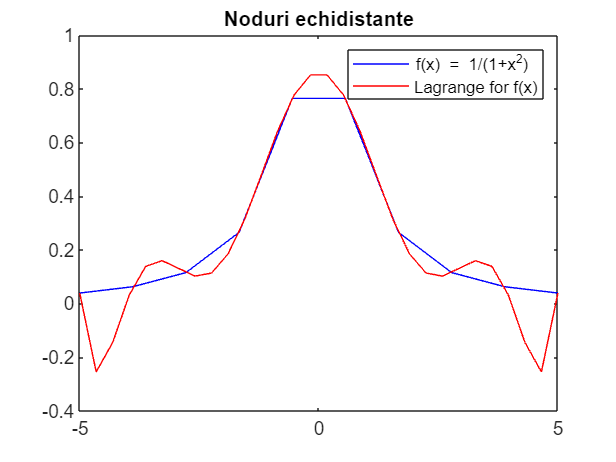



x = linspace(-5,5,10);
plot(x,f(x),'blue');
hold on
t = linspace(-5,5,30); 
y = f(x);
v = Lagrange(x,y,t);
plot(t,v,'red');
legend('f(x) = 1/(1+x^2)','Lagrange for f(x)')
title("Noduri echidistante")
hold off

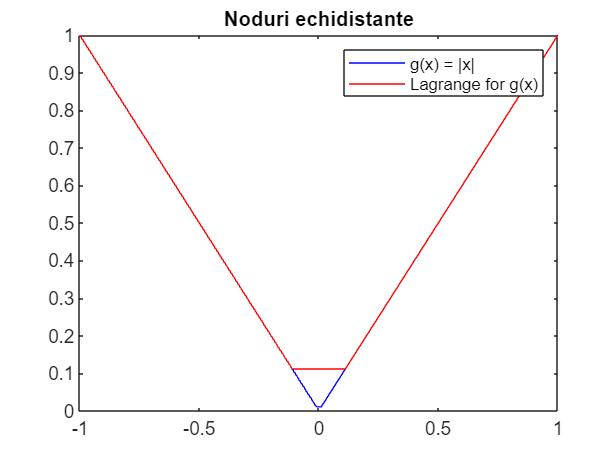


% ============ b) =============== 
clear all
syms x
g(x) = abs(x);

x = linspace(-1,1,100);
plot(x,g(x),'blue');
hold on
t = linspace(-1,1,10); 
y = g(x);
v = Lagrange(x,y,t);
plot(t,v,'red');
legend('g(x) = |x|','Lagrange for g(x)')
title("Noduri echidistante")
hold off

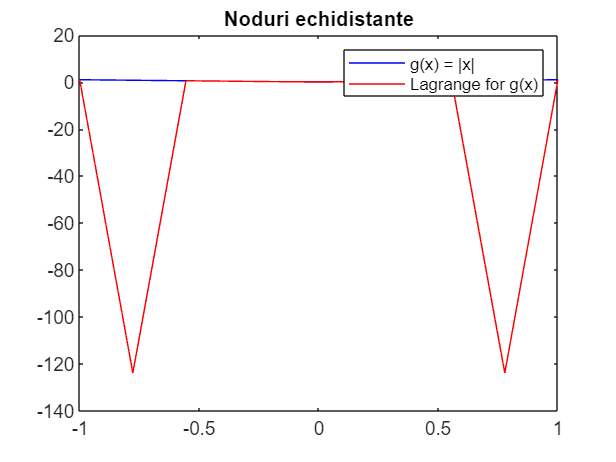


x = linspace(-1,1,50);
plot(x,g(x),'blue');
hold on
t = linspace(-1,1,10); 
y = g(x);
v = Lagrange(x,y,t);
plot(t,v,'red');
legend('g(x) = |x|','Lagrange for g(x)')
title("Noduri echidistante")
hold off

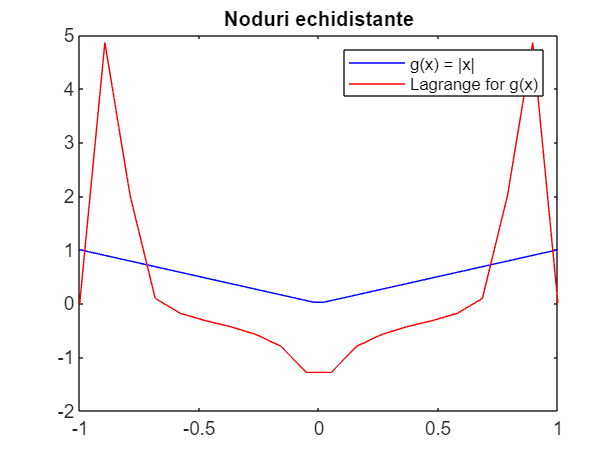


warning off
x = linspace(-1,1,50);
plot(x,g(x),'blue');
hold on
t = linspace(-1,1,20); 
y = g(x);
v = Lagrange(x,y,t);
plot(t,log10(v),'red');
legend('g(x) = |x|','Lagrange for g(x)')
title("Noduri echidistante")
hold off

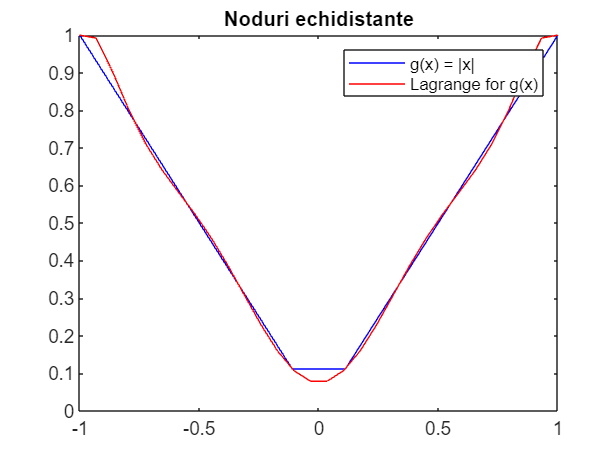


x = linspace(-1,1,10);
plot(x,g(x),'blue');
hold on
t = linspace(-1,1,30); 
y = g(x);
v = Lagrange(x,y,t);
plot(t,v,'red');
legend('g(x) = |x|','Lagrange for g(x)')
title("Noduri echidistante")
hold off

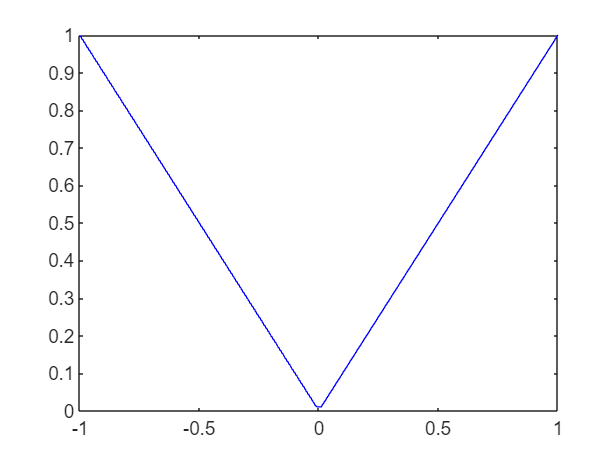


x = linspace(-1,1,100);
plot(x,g(x),'blue');

## Noduri Cebisev de speta 2

## a)

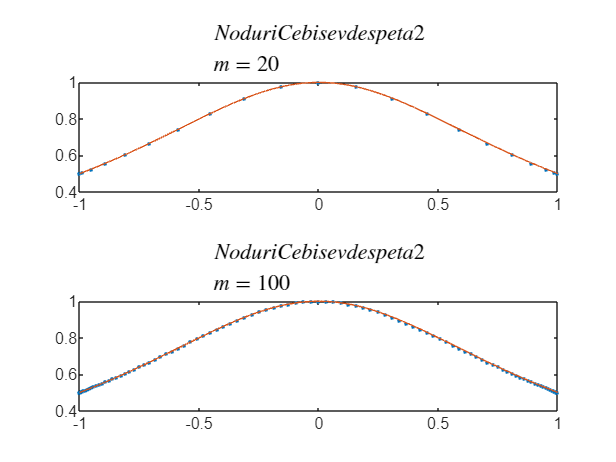

% ============ a) =============== 
m = 20;
fun = @(x) 1./(1+x.^2);
x = sort(cos(pi*(0:m)/m));
f = fun(x);
xx = linspace(-1,1,5000);
ff=ChebLagrange(f,xx);
subplot(2,1,1)
plot(x,f,'.',xx,ff,'-')
m = 100;
x = sort(cos(pi*(0:m)/m));
f = fun(x);
xx = linspace(-1,1,5000);
ff=ChebLagrange(f,xx);
title('$Noduri Cebisev de speta 2\\m=20$','Interpreter','LaTeX','FontSize',12)
subplot(2,1,2)
plot(x,f,'.',xx,ff,'-')
title('$Noduri Cebisev de speta 2\\m=100$','Interpreter','LaTeX','FontSize',12)

## b)

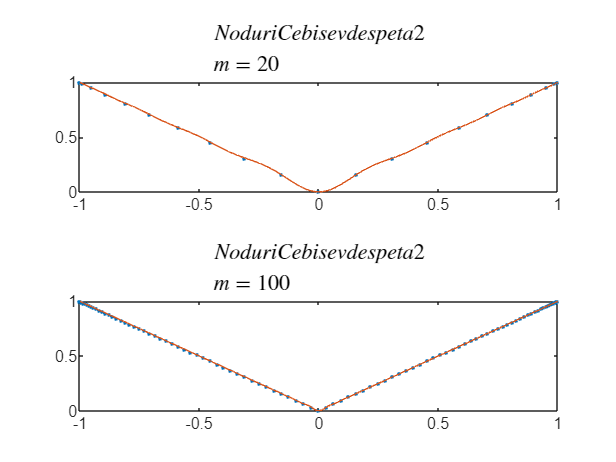

% ============ b) =============== 
hold off
clear all
syms x
m = 20;
fun = @(x) abs(x);
x = sort(cos(pi*(0:m)/m));
f = fun(x);
xx = linspace(-1,1,5000);
ff=ChebLagrange(f,xx);
subplot(2,1,1)
plot(x,f,'.',xx,ff,'-')
m = 100;
x = sort(cos(pi*(0:m)/m));
f = fun(x);
xx = linspace(-1,1,5000);
ff=ChebLagrange(f,xx);
title('$Noduri Cebisev de speta 2\\m=20$','Interpreter','LaTeX','FontSize',12)
subplot(2,1,2)
plot(x,f,'.',xx,ff,'-')
title('$Noduri Cebisev de speta 2\\m=100$','Interpreter','LaTeX','FontSize',12)
hold off

## P5

hold off
x = [0 pi/6 pi/4 pi/3 pi/2];
sin_x = [0 1/2 sqrt(2)/2 sqrt(3)/2 1];
cos_x = [1 sqrt(3)/2 sqrt(2)/2 1/2 0];

% ============ sin(5) =============
t=pi/36;
v = Lagrange(x,sin_x,t);
fprintf("My Lagrange sin5: %f",v);

My Lagrange sin5: 0.086913

fprintf("MATLAB sin5: %f",sin(t));

MATLAB sin5: 0.087156

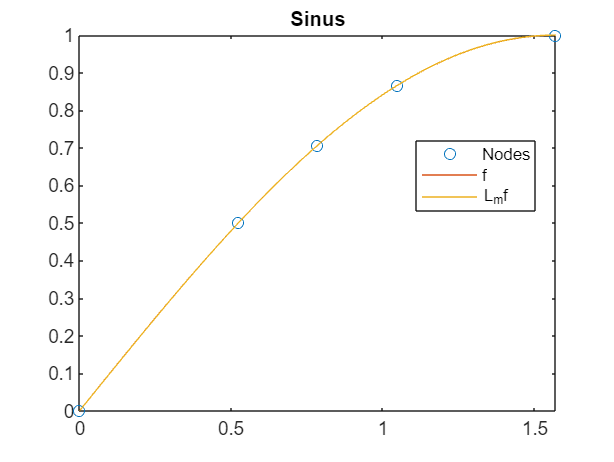



t=linspace(0,pi/2,100);
vl=Lagrange(x,sin_x,t);
plot(x,sin_x,'o',t,sin(t),t,vl)
legend('Nodes','f','L_mf','Location', 'best')
title('Sinus')
hold off



% ============ cos(5) =============
t=pi/36;
v = Lagrange(x,cos_x,t);
fprintf("My Lagrange cos5: %f",v);

My Lagrange cos5: 0.996386

fprintf("MATLAB cos5: %f",cos(t));

MATLAB cos5: 0.996195

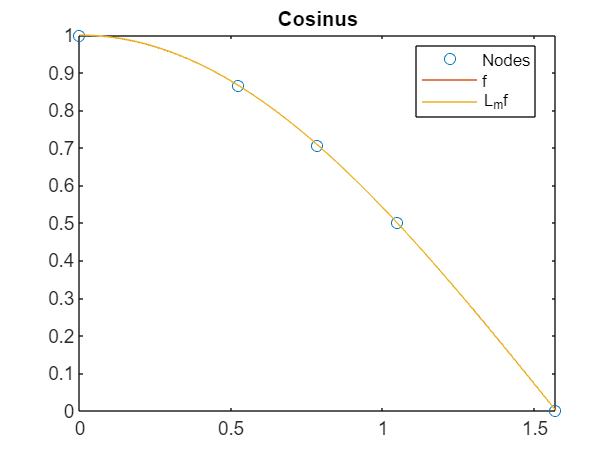



t=linspace(0,pi/2,100);
vl=Lagrange(x,cos_x,t);
plot(x,cos_x,'o',t,cos(t),t,vl)
legend('Nodes','f','L_mf','Location', 'best')
title('Cosinus')
hold off